# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 06-Apr-2024 12:35:39

## Set up the Import Options and import the data

clearvars
opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [1, inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["Time", "CAN Channel", "ID", "Rx", "D", "DLC", "Byte0", "Byte1", "Byte2", "Byte3", "Byte4", "Byte5", "Byte6", "Byte7", "VarName15"];
opts.VariableTypes = ["double", "double", "double", "string", "string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts = setvaropts(opts, "D", "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["Time", "DLC"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Time", "DLC"], "ThousandsSeparator", ",");

% Import the data
TriggerF1 = readtable("/Users/suyash/Downloads/Suyash/2024-07-19_18-47-24/TriggerF014.asc", opts);

## Clear temporary variables

clear opts

#### FDN

FDN = TriggerF1(TriggerF1.ID == 0x302,:);
front_sensor = sensor_decode(FDN);
front_sensor;
RPM_Left = table(front_sensor.Time, front_sensor.Sens5,'VariableNames',{'Time','Voltag'});
plot(front_sensor.Time, front_sensor.Sens5)
graphics("RPM Left", "RPM")
RPM_right = table(front_sensor.Time, front_sensor.Sens6,'VariableNames',{'Time','Voltag'});
plot(front_sensor.Time, front_sensor.Sens6)
graphics("RPM Right", "RPM")
plot(front_sensor.Time, 5*(front_sensor.Sens4)/1023)

graphics("Sus Left", "Signal(V)")

### Sus_Front_Left

    sus_front_left = table(front_sensor.Time, 5 * (front_sensor.Sens4) / 1023,'VariableNames', {'Time', 'Voltage'});
    plot(front_sensor.Time, 5 * (front_sensor.Sens4) / 1023)
    graphics("Sus_Front_Left", "Signal(V)")

### Sus_Front_Right

     sus_front_right = table(front_sensor.Time, 5*(front_sensor.Sens3)/1023,'VariableNames', {'Time', 'Voltage'});

### Yaw_data

%Yaw_data = TriggerF1(TriggerF1.ID == 0x70, :);
yaw_rate = Yaw_rate_decode(TriggerF1);
graphics("Yaw Rate", "°/s")
Acc_Y = Acc_Y_decode(TriggerF1);
Acc_x = Acc_x_decode(TriggerF1);
Yaw_accn = Yaw_accn_decode(TriggerF1);

#### RDN

% RDN = TriggerF1(TriggerF1.ID == 0x104);
% rear_sensor = sensor_decode(RDN);
% rear_sensor;

### Sus_Rear_Left

    % sus_rear_left = table(rear_sensor.Time, 5 * (rear_sensor.Sens4) / 1023,'VariableNames', {'Time', 'Voltage'});
    % plot(rear_sensor.Time, 5 * (rear_sensor.Sens4) / 1023)
    % graphics("Sus_Rear_Left", "Signal(V)")

### Sus_Rear_Right

    %  sus_rear_right = table(rear_sensor.Time, 5*(rear_sensor.Sens3)/1023,'VariableNames', {'Time', 'Voltage'});

#### Actuator

Act = TriggerF1(TriggerF1.ID == 0x104,:);
Act_sensor = actuator_decode(Act);
Act_sensor;

### **Steering**

Steer_data = table(Act_sensor.Time, 5*(Act_sensor.Sens5)/1023,'VariableNames',{'Time','Voltage'});

#### ECU to MC

    MC_left

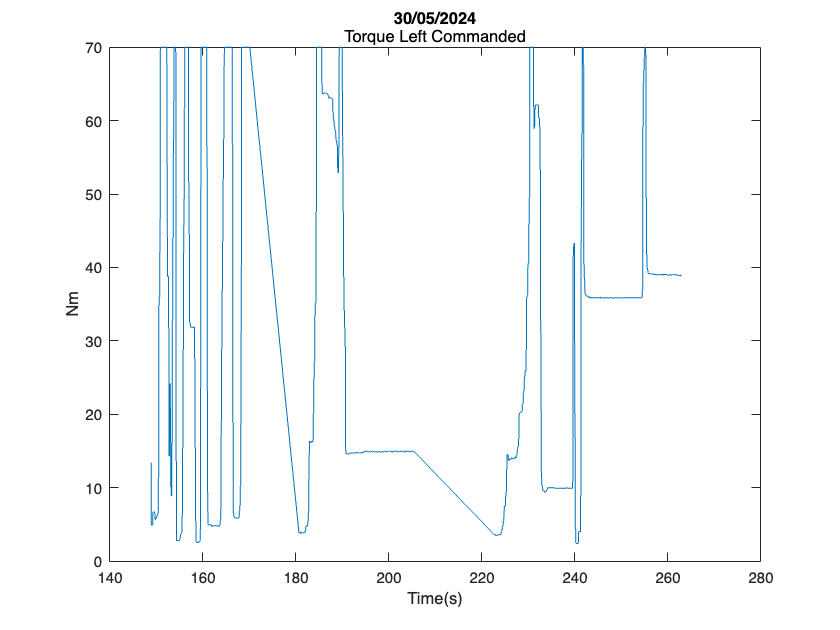

left_cmd = TriggerF1(TriggerF1.ID == 0x201,:);
torque_left_ecu = torque_decode_ecu(left_cmd);
plot(torque_left_ecu.Time, torque_left_ecu.Torque)
graphics("Torque Left Commanded", "Nm")

    MC_right

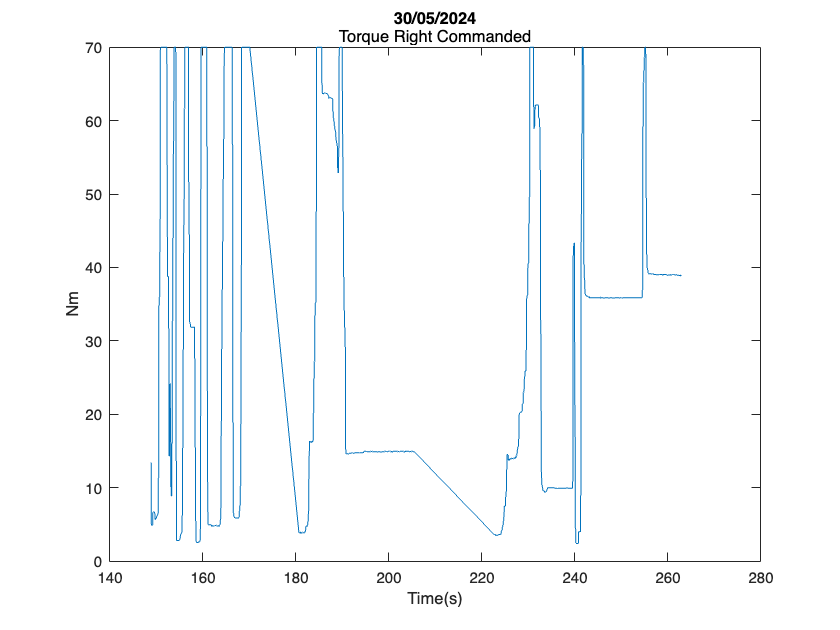

right_cmd = TriggerF1(TriggerF1.ID == 0x202,:);
torque_right_ecu = torque_decode_ecu(right_cmd);
plot(torque_right_ecu.Time, torque_right_ecu.Torque)
graphics("Torque Right Commanded", "Nm")

#### MC to ECU

    MC_left

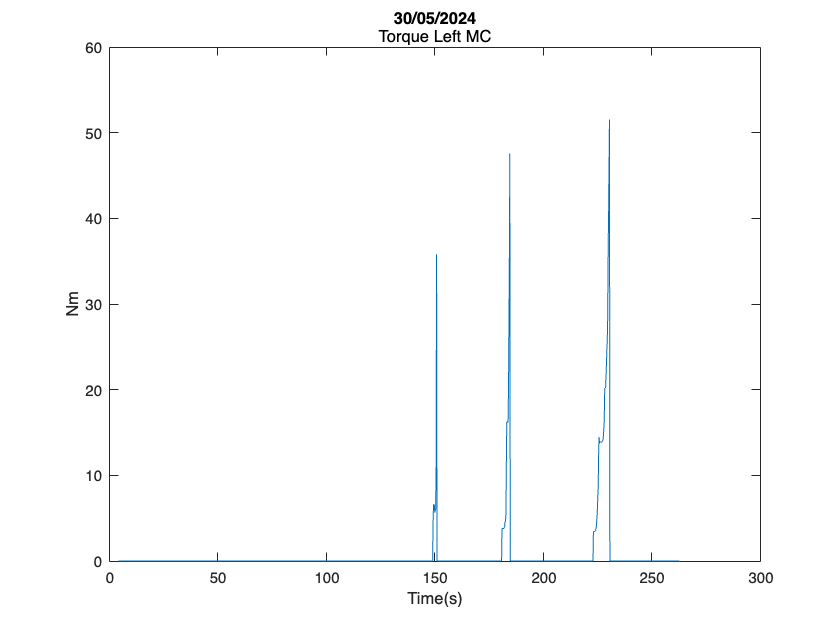

left_rec = TriggerF1(TriggerF1.ID == 0x181,:);

torque_left_mc = torque_decode_mc(left_rec);
figure();
plot(torque_left_mc.Time, torque_left_mc.Torque)
graphics("Torque Left MC", "Nm")

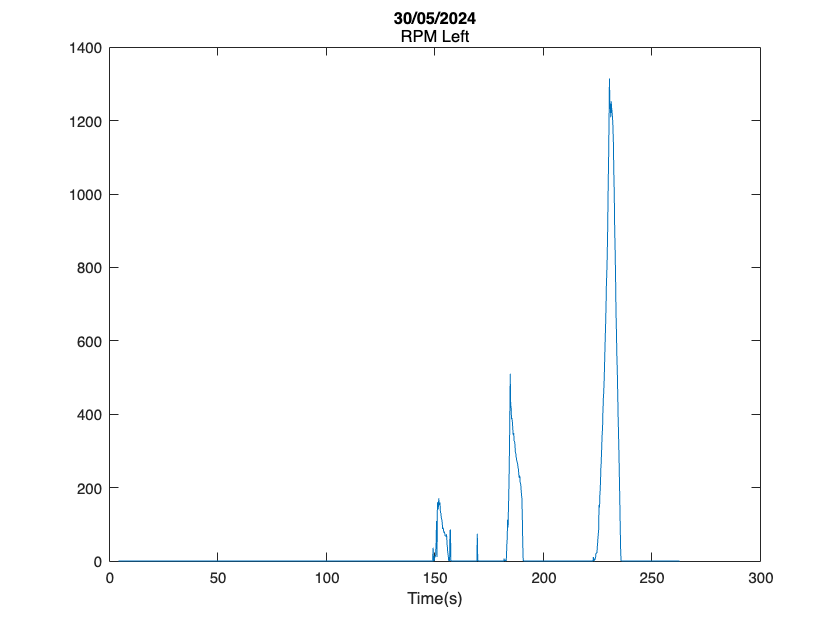


rpm_left_mc = rpm_decode_mc(left_rec, 10000);
figure();
plot(rpm_left_mc.Time, rpm_left_mc.RPM)
graphics("RPM Left", "")

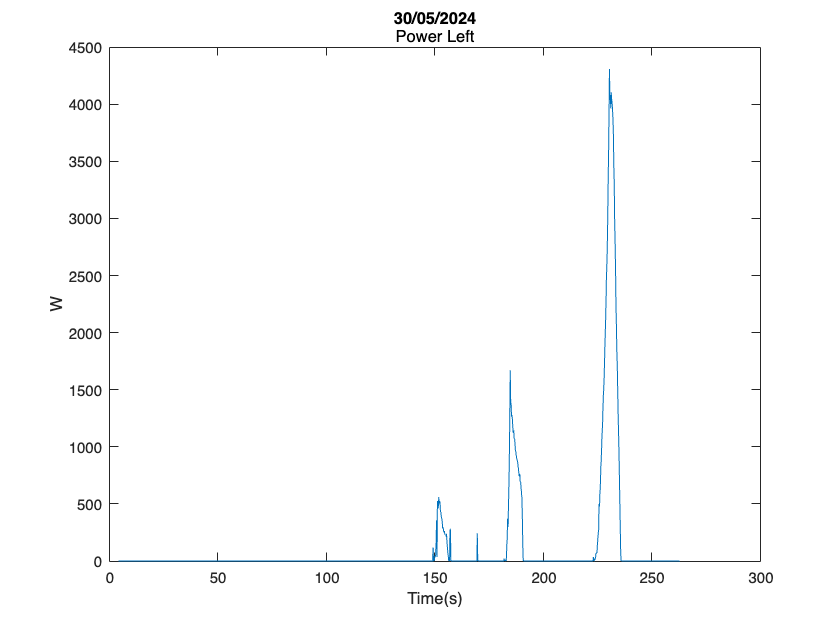


power_left_mc = power_decode_mc(left_rec);
figure();
plot(power_left_mc.Time, power_left_mc.Power)
graphics("Power Left", "W")

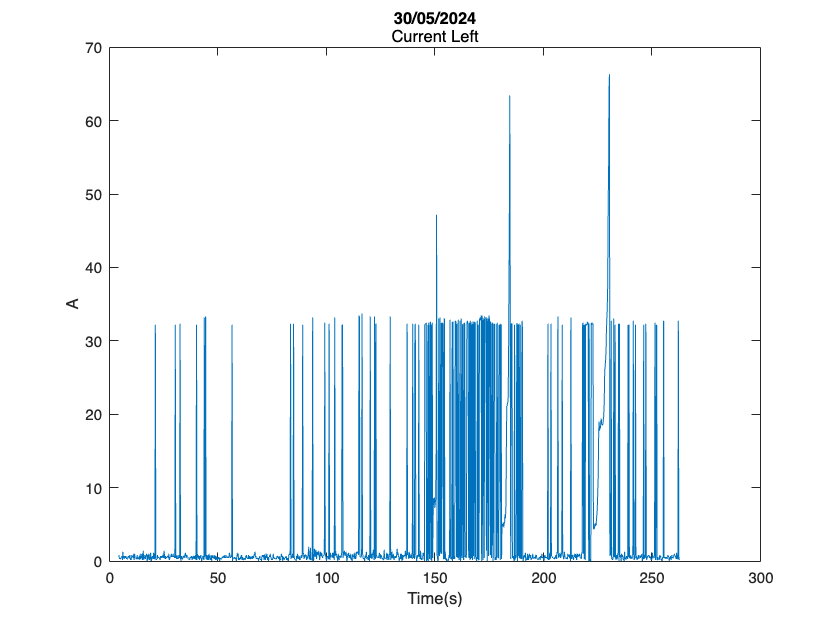


current_left_mc = current_decode_mc(left_rec);
figure();
plot(current_left_mc.Time, current_left_mc.Current)
graphics("Current Left", "A")

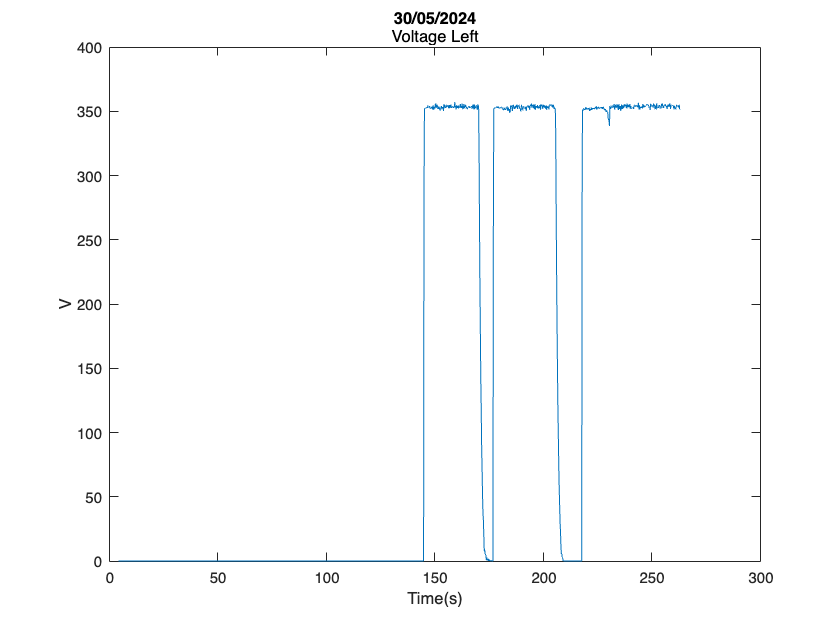


voltage_left_mc = voltage_decode_mc(left_rec);
figure();
plot(voltage_left_mc.Time, voltage_left_mc.Voltage)
graphics("Voltage Left", "V")

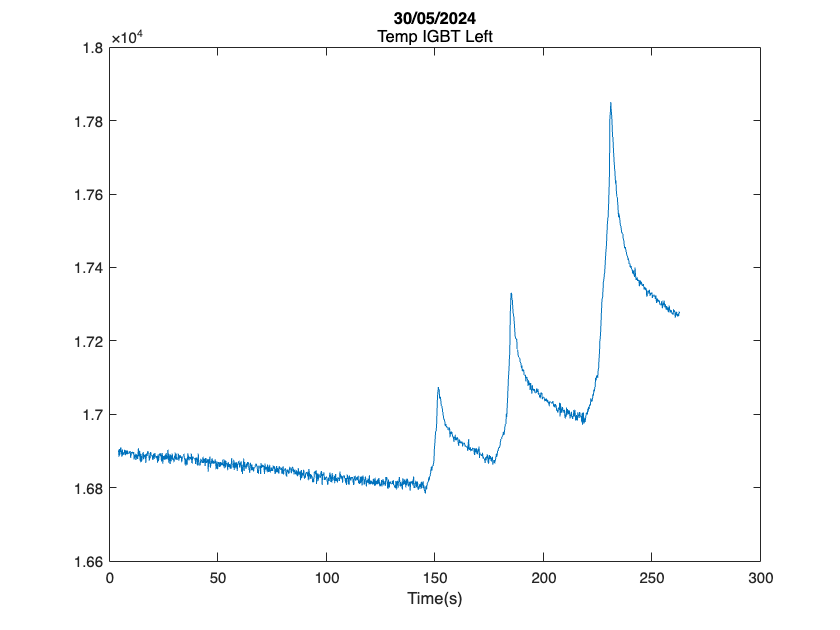


temp_igbt_left_mc = temp_igbt_decode_mc(left_rec);
figure();
plot(temp_igbt_left_mc.Time, temp_igbt_left_mc.Temp)
graphics("Temp IGBT Left", "")

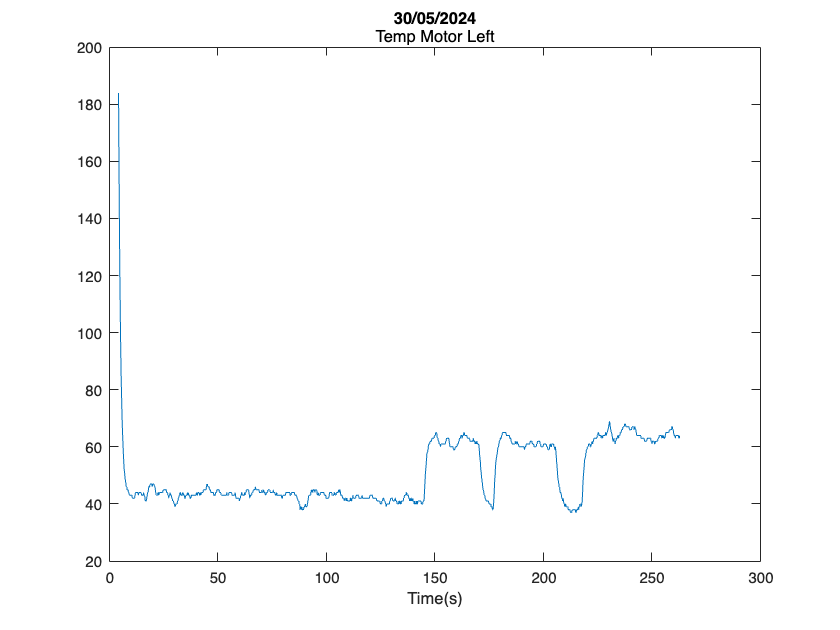


temp_motor_left_mc = temp_motor_decode_mc(left_rec);
figure();
plot(temp_motor_left_mc.Time, temp_motor_left_mc.Temp)
graphics("Temp Motor Left", "")

    MC_right

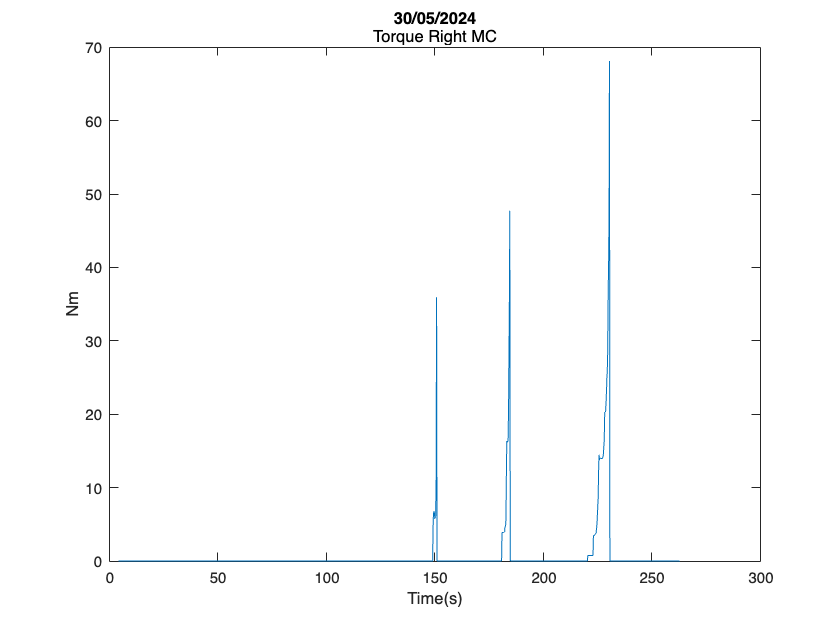

right_rec = TriggerF1(TriggerF1.ID == 0x182,:);

torque_right_mc = torque_decode_mc(right_rec);
figure();
plot(torque_right_mc.Time, torque_right_mc.Torque)
graphics("Torque Right MC", "Nm")

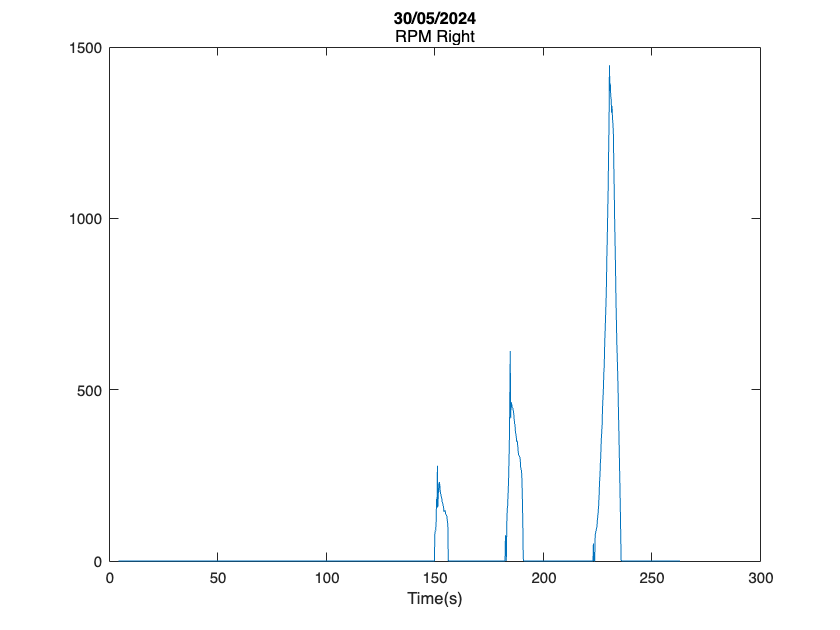


rpm_right_mc = rpm_decode_mc(right_rec, 10000);
figure();
plot(rpm_right_mc.Time, rpm_right_mc.RPM)
graphics("RPM Right", "")

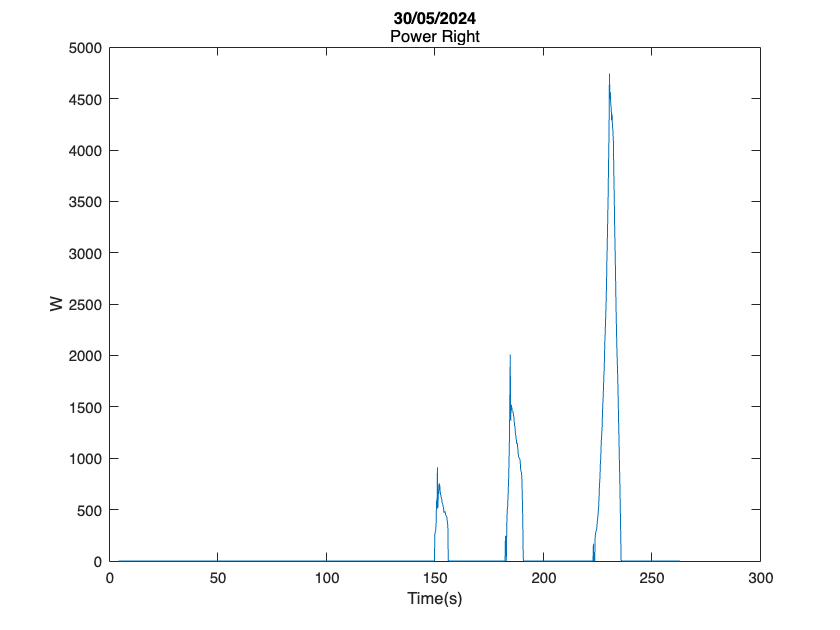


power_right_mc = power_decode_mc(right_rec);
figure();
plot(power_right_mc.Time, power_right_mc.Power)
graphics("Power Right", "W")

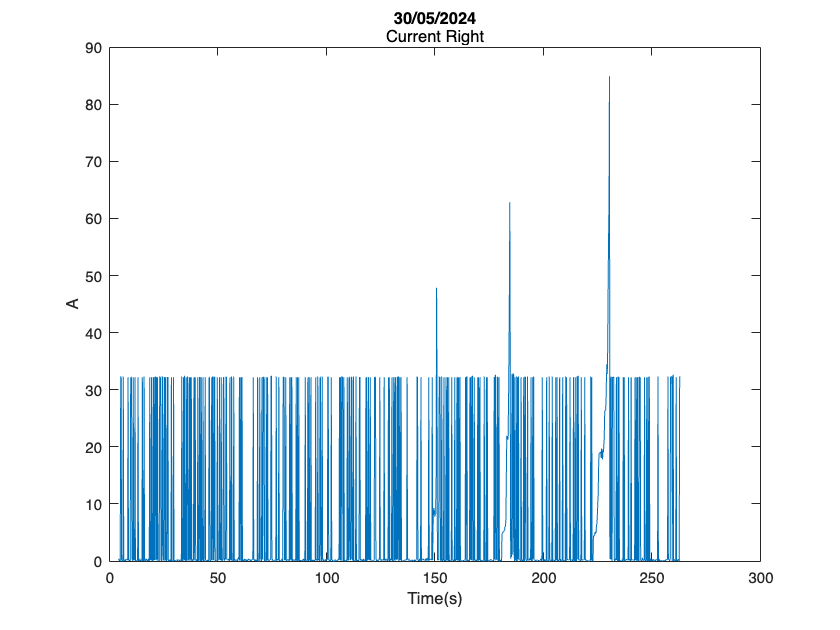


current_right_mc = current_decode_mc(right_rec);
figure();
plot(current_right_mc.Time, current_right_mc.Current)
graphics("Current Right", "A")

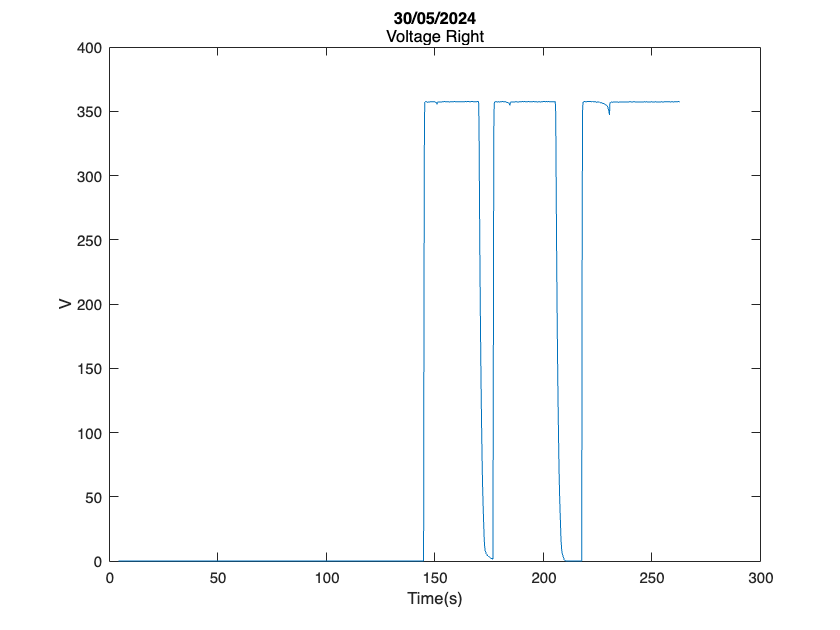


voltage_right_mc = voltage_decode_mc(right_rec);
figure();
plot(voltage_right_mc.Time, voltage_right_mc.Voltage)
graphics("Voltage Right", "V")

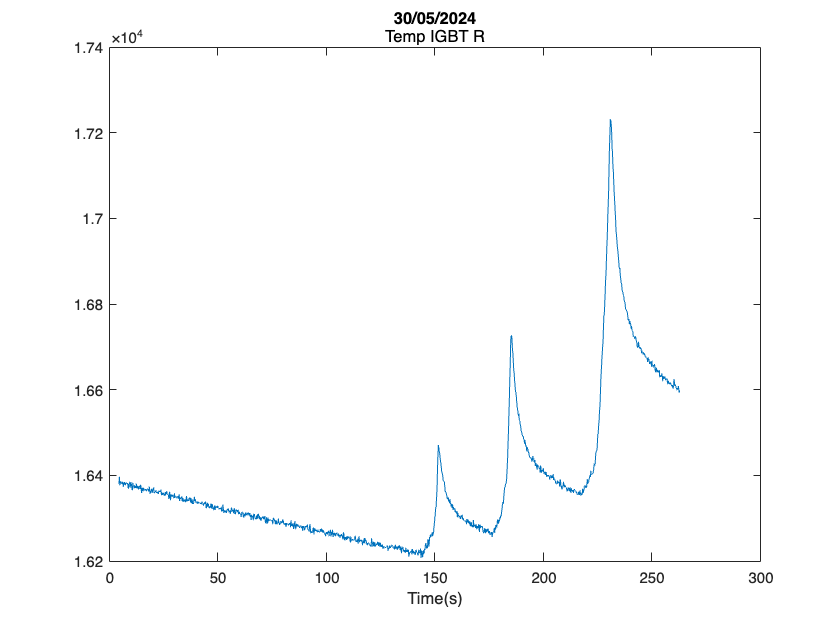


temp_igbt_right_mc = temp_igbt_decode_mc(right_rec);
figure();
plot(temp_igbt_right_mc.Time, temp_igbt_right_mc.Temp);
graphics("Temp IGBT R", "")

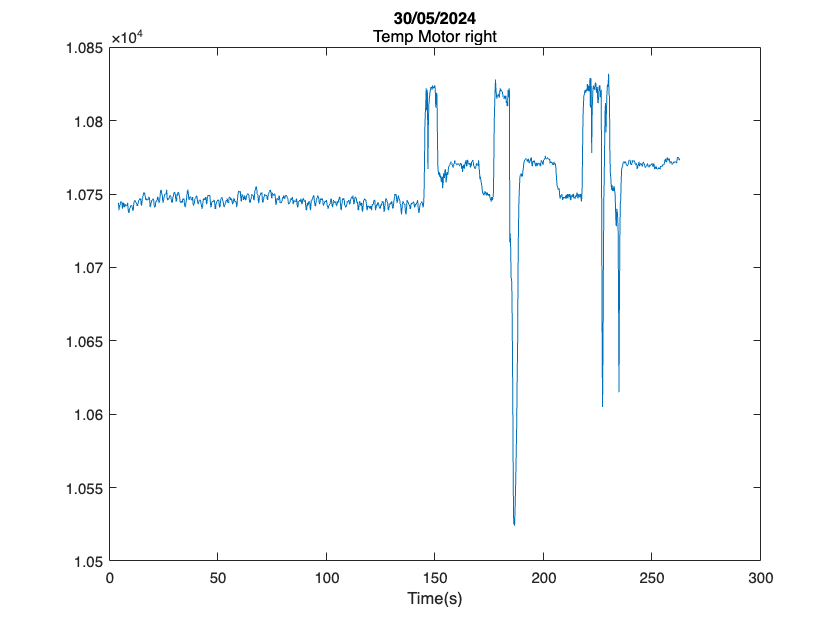



temp_motor_right_mc = temp_motor_decode_mc(right_rec);

plot(temp_motor_right_mc.Time, temp_motor_right_mc.Temp)
graphics("Temp Motor right", "")

#### Graphs

function graphics(data_name, data_label)
    title("30/05/2024")
    subtitle(data_name);
    xlabel("Time(s)")
    ylabel(data_label)
end

#### Decode functions

    Actuator data

function sensor_data = actuator_decode(data)
    data = str2double(table2array(data));
    Time = data(:,1);
    Sens1 = bitshift(bitand(data(:,8),3),8) + bitshift(data(:,7),0);
    Sens2 = bitshift(bitand(data(:,9),15),6) + bitshift(data(:,8),-2);
    Sens3 = bitshift(bitand(data(:,10),63),4) + bitshift(data(:,9),-4);
    Sens4 = bitshift(bitand(data(:,11),255),2) + bitshift(data(:,10),-6);
    Sens5 = bitshift(bitand(data(:,13),3),8) + bitshift(data(:,12),0);
    Sens6 = bitshift(bitand(data(:,14),15),6) + bitshift(data(:,13),-2);
    sensor_data = table(Time, Sens1, Sens2, Sens3, Sens4, Sens5, Sens6);
end

    Sensor data

function sensor_data = sensor_decode(data)
    data = str2double(table2array(data));
    Time = data(:,1);
    Sens1 = bitshift(bitand(data(:,8),3),8) + bitshift(data(:,7),0);
    Sens2 = bitshift(bitand(data(:,9),15),6) + bitshift(data(:,8),-2);
    Sens3 = bitshift(bitand(data(:,10),63),4) + bitshift(data(:,9),-4);
    Sens4 = bitshift(bitand(data(:,11),255),2) + bitshift(data(:,10),-6);
    Sens5 = bitshift(bitand(data(:,13),15),8) + bitshift(data(:,12),0);
    Sens6 = bitshift(bitand(data(:,14),255),0) + bitshift(data(:,13),-4);
    sensor_data = table(Time, Sens1, Sens2, Sens3, Sens4, Sens5, Sens6);
end

    Torque_ecu

function torque_data = torque_decode_ecu(data)
    data = str2double(table2array(data(data.Byte0 == 0x90, :)));
    Time = data(:,1);
    dummy = bitshift(data(:,9),8) + data(:,8);
    Torque = 90*(min(dummy, (65767*ones(size(Time)) - dummy)))/32767;
    torque_data = table(Time, Torque);
end

  Torque_mc

function torque_data = torque_decode_mc(data)
    data = str2double(table2array(data(data.Byte0 == 0xA0, :)));
    Time = data(:,1);
    dummy = bitshift(data(:,9),8) + data(:,8);
    Torque = 90*(min(dummy, (65767*ones(size(Time)) - dummy)))/32767;
    torque_data = table(Time, Torque);
end

  RPM_mc

function rpm_data = rpm_decode_mc(data,rpm_max)
    data = str2double(table2array(data(data.Byte0 == 0x30, :)));
    Time = data(:,1);
    dummy = bitshift(data(:,9),8) + data(:,8);
    RPM = rpm_max*(min(dummy, (65767*ones(size(Time)) - dummy)))/32767;
    rpm_data = table(Time, RPM);
end

    Power_mc

function power_data = power_decode_mc(data)
    data = str2double(table2array(data(data.Byte0 == 0x30, :)));
    Time = data(:,1);
    dummy = bitshift(data(:,9),8) + data(:,8);
    Power = min(dummy, (65767*ones(size(Time)) - dummy));
    power_data = table(Time, Power);
end

    Current

function current_data = current_decode_mc(data)
    data = str2double(table2array(data(data.Byte0 == 0x20, :)));
    Time = data(:,1);
    dummy = bitshift(data(:,9),8) + data(:,8);
    Current = 800*2*min(dummy, (65767*ones(size(Time)) - dummy))/11530;
    current_data = table(Time, Current);
end

    Volatge

function voltage_data = voltage_decode_mc(data)
    data = str2double(table2array(data(data.Byte0 == 0xEB, :)));
    Time = data(:,1);
    Voltage = (bitshift(data(:,9),8) + data(:,8))/31.548;
    voltage_data = table(Time, Voltage);
end

    Temp_mc_igbt

function temp_igbt_data = temp_igbt_decode_mc(data)
    data = str2double(table2array(data(data.Byte0 == 0x4a, :)));
    Time = data(:,1);
    Temp = (bitshift(data(:,9),8) + data(:,8));
    temp_igbt_data = table(Time, Temp);
end

    Temp_motor

function temp_motor_data = temp_motor_decode_mc(data)
    data = str2double(table2array(data(data.Byte0 == 0x49, :)));
    Time = data(:,1);
    Temp = (bitshift(data(:,9),8) + data(:,8));
    temp_motor_data = table(Time, Temp);
end

Yaw_rate

function yaw_rate_data = Yaw_rate_decode(data)
    data = str2double(table2array(data(data.ID == 0x70, :)));
    Time  = data(:,1);
    yaw_rate = bitshift(data(:,8),8) + data(:,7);
    %condition_met_indices = yaw_rate > 32767;
    %condition_met_indices2 = yaw_rate < 32768;
    %yaw_rate(condition_met_indices) = yaw_rate(condition_met_indices) - 65536;
    %yaw_rate(condition_met_indices1) = 32768 - yaw_rate(condition_met_indices1) ;
    %yaw_rate(condition_met_indices2)= yaw_rate(condition_met_indices2) - 32768;
    yaw_rate = yaw_rate - 32768;
    yaw_rate = yaw_rate*0.005 * (pi/180);
    yaw_rate_data = table(Time, yaw_rate);
   
end

Acc_Y

function acc_y_data = Acc_Y_decode(data)
    data = str2double(table2array(data(data.ID == 0x70, :)));
    Time  = data(:,1);
    acc_y = bitshift(data(:,12),8) + data(:,11);
    acc_y = acc_y -32768;
    acc_y = acc_y*0.0001274*9.80665;
    acc_y_data = table(Time,acc_y);
end

Acc_x

function acc_x_data = Acc_x_decode(data)
    data = str2double(table2array(data(data.ID == 0x80, :)));
    Time  = data(:,1);
    acc_x = bitshift(data(:,12),8) + data(:,11);
    acc_x = acc_x - 32768;
    acc_x = acc_x*0.0001274*9.80665;
    acc_x_data = table(Time,acc_x);
end

Yaw acceleration

function yaw_accn_data = Yaw_accn_decode(data)
    data = str2double(table2array(data(data.ID == 0x80, :)));
    Time  = data(:,1);
    yaw_accn = bitshift(data(:,8),8) + data(:,7);
    %condition_met_indices = yaw_rate > 32767;
    %condition_met_indices2 = yaw_rate < 32768;
    %yaw_rate(condition_met_indices) = yaw_rate(condition_met_indices) - 65536;
    %yaw_rate(condition_met_indices1) = 32768 - yaw_rate(condition_met_indices1) ;
    %yaw_rate(condition_met_indices2)= yaw_rate(condition_met_indices2) - 32768;
    yaw_accn = yaw_accn - 32768;
    yaw_accn = yaw_accn*0.125;
    yaw_accn_data = table(Time, yaw_accn);
   
end